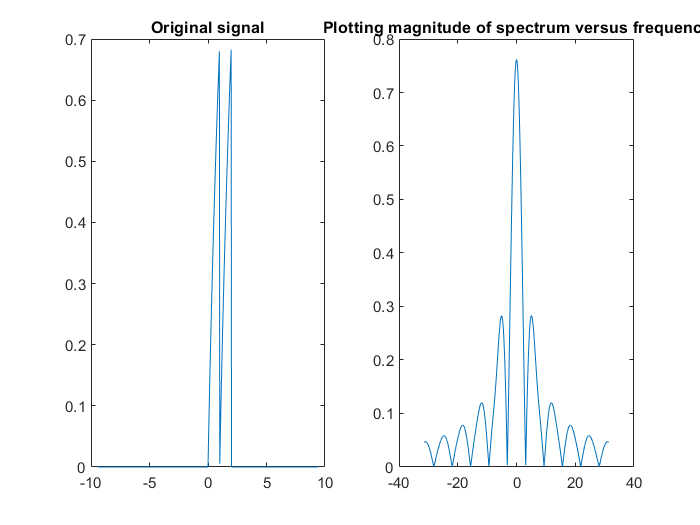

clear
clc
close all

w=-10*pi:0.01*pi:10*pi;
t=-3*pi:0.01*pi:3*pi;
% PROBLEM 1   
x=f7(t);subplot(1,2,1);
plot(t,x);title('Original signal');

x_w=zeros(size(w));
for i=1:length(w)
    k=w(i);
    basis1=exp(-1i*k*t);
    x_w(i)=trapz(t,x.*basis1);
end 
subplot(1,2,2);plot(w,abs(x_w));
title('Plotting magnitude of spectrum versus frequency');

disp("The highest magnitude of frequency (p) is 0.7618");

The highest magnitude of frequency (p) is 0.7618


p=0.7618;p1=p/sqrt(2);
disp("We plot p/sqrt(2) points on the graph");

We plot p/sqrt(2) points on the graph


omega1=-1.445;omega2=1.445;
disp("We get omega1=-1.445 and omega2=1.445");

We get omega1=-1.445 and omega2=1.445


BW=omega2-omega1;disp("Bandwidth");

Bandwidth


disp(BW);Nyquist_rate=2*BW;

    2.8900



disp("Nyquist sampling rate");disp(Nyquist_rate);

Nyquist sampling rate
    5.7800

